Lambda = 0.0004;
mu = Lambda;
beta = 1.5;
gamma = 1;
epsilon = 1;
alpha_i = 0;
alpha_s = 0.0008;

par_keys = ["Lambda" "mu" "beta" "gamma" "epsilon" "alpha_i" "alpha_s"];
par_values = [Lambda mu beta gamma epsilon alpha_i alpha_s];
par_dictionary = dictionary(par_keys, par_values);

tmin = 40000;
tmax = 80000;
tspan = [0 tmax];
eval_times = linspace(tmin, tmax, tmax - tmin + 1);
i0 = 1e-2;
x0 = [1 - i0; i0; 0];
options = odeset("RelTol", 1e-13, "AbsTol", 1e-16);

R0_min = 2.3;
R0_max = 3.2;
R0_vals = R0_min:0.05:R0_max;
beta_vals = R0_vals .* par_dictionary("Lambda") / par_dictionary("mu") / (par_dictionary("gamma") + par_dictionary("mu") + par_dictionary("alpha_i"));
I_avg = zeros(1, length(beta_vals));
I_min = zeros(1, length(beta_vals));
I_max = zeros(1, length(beta_vals));
I_star = zeros(1, length(beta_vals));

for i = 1:length(beta_vals)
    par_dictionary("beta") = beta_vals(i);
    EE = get_chadi_model_EE(par_dictionary);
    I_star(i) = EE(2);
    J_EE = chadi_jacobian(EE, par_dictionary);
    EE_stable = all(real(eig(J_EE)) < 0);
    if not(EE_stable)
        odefun = @(t,x) model(t, x, par_dictionary);
        sol = ode89(odefun, tspan, x0, options);
        time_series = deval(sol, eval_times);
        [peaks, peak_locs] = findpeaks(time_series(2,:), "MinPeakHeight", 1e-3);
        period = int32(mean(diff(eval_times(peak_locs))));
        num_periods = 4;
        I_time_series_one_period = time_series(2, end - num_periods*period:end);
        t = eval_times(end - num_periods*period:end);
        
        I_avg(i) = trapz(t, I_time_series_one_period) / (t(end) - t(1));
        I_min(i) = min(I_time_series_one_period);
        I_max(i) = max(I_time_series_one_period);

        fprintf("I_avg: %.12f\n", I_avg(i));
        fprintf("I_min: %.12f\n", I_min(i));
    else
        I_avg(i) = EE(2);
        I_min(i) = EE(2);
        I_max(i) = EE(2);
    end
end

I_avg: 0.006368639551


I_min: 0.000000000004


I_avg: 0.005871959467


I_min: 0.000000000375


I_avg: 0.005380940854


I_min: 0.000000015725


I_avg: 0.004894338012


I_min: 0.000000336615


I_avg: 0.004403878508


I_min: 0.000003996003


I_avg: 0.003903233223


I_min: 0.000028507750


I_avg: 0.003380662933


I_min: 0.000133525305


I_avg: 0.002873330718


I_min: 0.000470667406



I_avg

I_avg =     0.0064    0.0059    0.0054    0.0049    0.0044    0.0039    0.0034    0.0029    0.0024    0.0029    0.0036    0.0047    0.0065    0.0097    0.0159    0.0257    0.0382    0.0518    0.0656


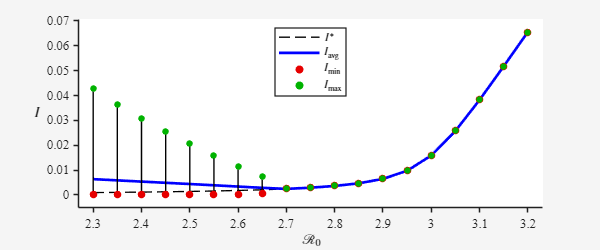

fig = figure("Position", [0 0 600 250]);
axis = axes(fig);
hold on;

plot(R0_vals, I_star, "DisplayName", "$I^*$", "Color", [0 0 0], "LineWidth", 1, "LineStyle", "--");
plot(R0_vals, I_avg, "DisplayName", "$I_\mathrm{avg}$", "Color", [0 0 1], "LineWidth", 2);
for i = 1:length(R0_vals)
    plot([R0_vals(i), R0_vals(i)], [I_min(i), I_max(i)], "HandleVisibility", "off", "Color", [0 0 0], "LineWidth", 0.67);
end
scatter(R0_vals, I_min, 32, [0.9 0 0], "filled", "DisplayName", "$I_\mathrm{min}$");
scatter(R0_vals, I_max, 24, [0 0.7 0], "filled", "DisplayName", "$I_\mathrm{max}$");

xlabel("$\mathcal{R}_0$", "Interpreter", "latex");
ylabel("$I$", "Interpreter", "latex", "Rotation", 0)
legend("Interpreter", "latex", "Location", "north");
xticks(R0_min:0.1:R0_max);
axis.XAxis.TickLength = [0.01 0];
axis.XAxis.FontName = "Times New Roman";
axis.YAxis.TickLength = [0.01 0];
axis.YAxis.FontName = "Times New Roman";
set(axis, "TickDir", "out");

%box(axis, "on");
axis.LineWidth = 1;

% Add axis padding
xlen = R0_vals(end) - R0_vals(1);
x_pad = xlen*0.035;
xlim([R0_vals(1) - x_pad, R0_vals(end) + x_pad]);

ymax = max(I_max);
y_pad = ymax*0.08;
ylim([-y_pad, ymax + y_pad]);

theme(fig, "light");
hold off;

exportgraphics(fig, "Iavg_diagram.pdf", "Resolution", 300);

function dx_dt = model(t, x, par_dictionary)
    Lambda = par_dictionary("Lambda");
    mu = par_dictionary("mu");
    beta = par_dictionary("beta");
    gamma = par_dictionary("gamma");
    epsilon = par_dictionary("epsilon");
    alpha_i = par_dictionary("alpha_i");
    alpha_s = par_dictionary("alpha_s");

    Sp = x(1);
    I = x(2);
    Ss = x(3);

    dSp_dt = Lambda - beta*Sp*I - mu*Sp;
    dI_dt = beta*Sp*I + epsilon*beta*Ss*I - (gamma + mu + alpha_i)*I;
    dSs_dt = gamma*I - epsilon*beta*Ss*I - (mu + alpha_s)*Ss;

    dx_dt = [dSp_dt; dI_dt; dSs_dt];
end

% Calculate the location of the endeimc equilibrium analytically using the
% equations in the Supplemental Material of Saad-Roy et al. (2023)
function x_star = get_chadi_model_EE(par_dictionary)
    Lambda = par_dictionary("Lambda");
    mu = par_dictionary("mu");
    beta = par_dictionary("beta");
    gamma = par_dictionary("gamma");
    epsilon = par_dictionary("epsilon");
    alpha_i = par_dictionary("alpha_i");
    alpha_s = par_dictionary("alpha_s");

    A2 = -epsilon*beta*(mu + alpha_i);
    A1 = Lambda*epsilon*beta + epsilon*gamma*mu - (mu + gamma + alpha_i)/beta * (beta*(alpha_s + mu) + epsilon*beta*mu);
    A0 = Lambda*(alpha_s + mu) - (mu + gamma + alpha_i)/beta * mu*(alpha_s + mu);

    I_star = (-A1 - sqrt(A1^2 - 4*A0*A2)) / (2*A2);
    Ss_star = gamma*I_star / (epsilon*beta*I_star + alpha_s + mu);
    Sp_star = (mu + gamma + alpha_i)/beta - epsilon*Ss_star;

    x_star = [Sp_star; I_star; Ss_star];
end

function J = chadi_jacobian(x, par_dictionary)
    Lambda = par_dictionary("Lambda");
    mu = par_dictionary("mu");
    beta = par_dictionary("beta");
    gamma = par_dictionary("gamma");
    epsilon = par_dictionary("epsilon");
    alpha_i = par_dictionary("alpha_i");
    alpha_s = par_dictionary("alpha_s");

    Sp = x(1);
    I = x(2);
    Ss = x(3);

    J = [[-beta*I - mu, -beta*Sp, 0];
        [beta*I, beta*Sp + epsilon*beta*Ss - (gamma + mu + alpha_i), epsilon*beta*I];
        [0, gamma - epsilon*beta*Ss, -epsilon*beta*I - (mu + alpha_s)]];
end